K-means Segmentation Example

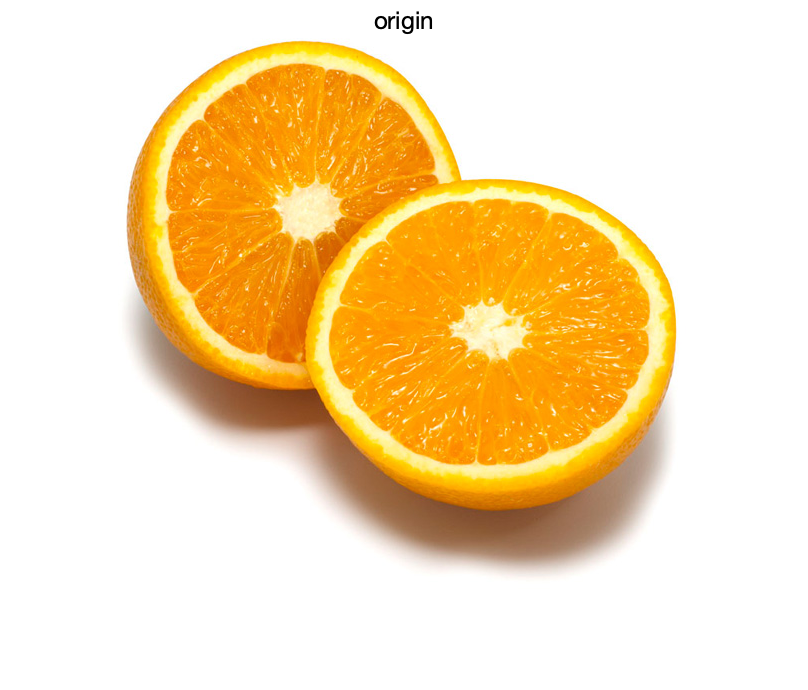

image = imread('orange.jpg');
% image = imread('tiger1.jpg');
% image = imread('tiger2.jpg');
% image = imread('tiger3.jpg');
imshow(image)
title('origin')

K_list = [5, 6, 7]

K_list =      5     6     7


L = 200

L = 200

converge at loop 24


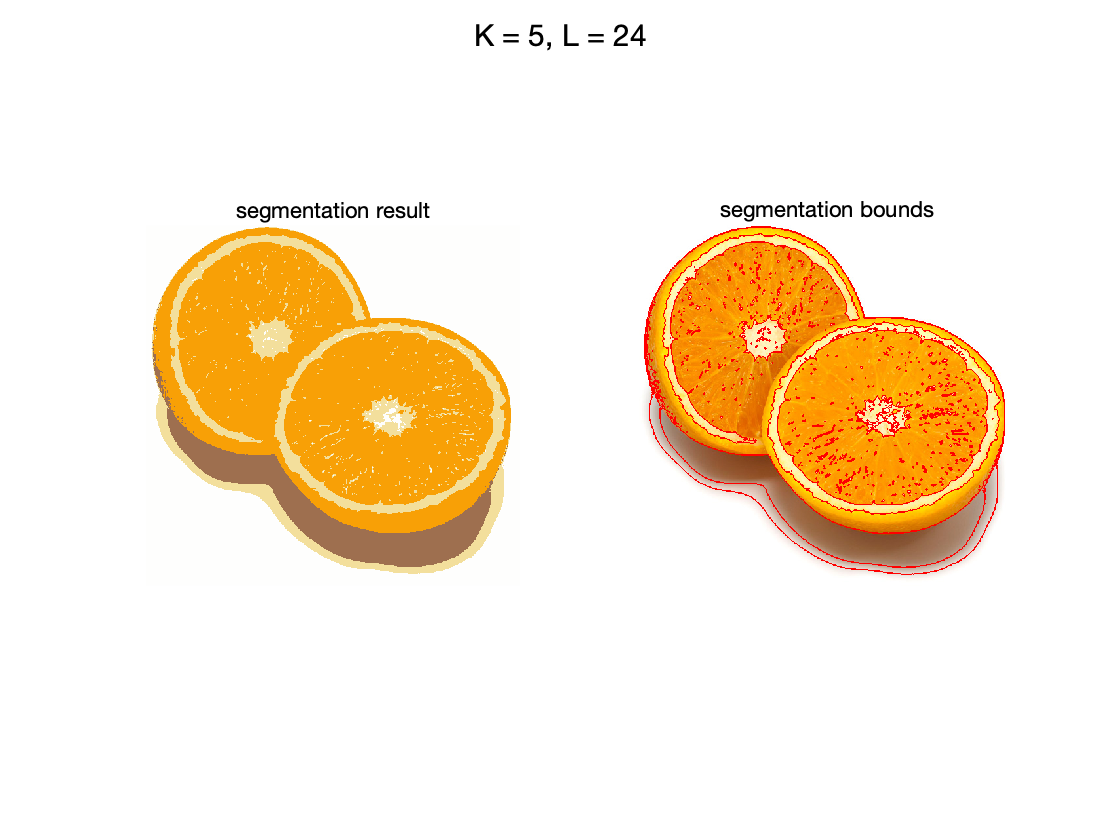

converge at loop 39


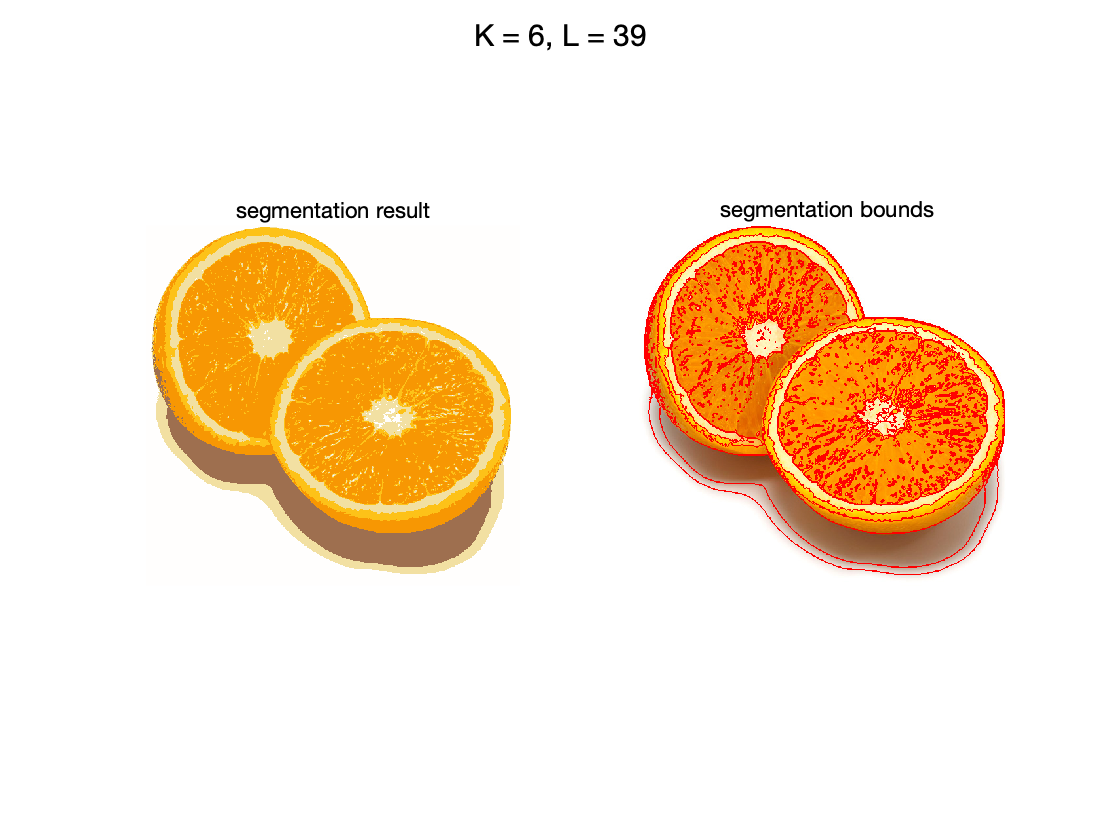

converge at loop 55


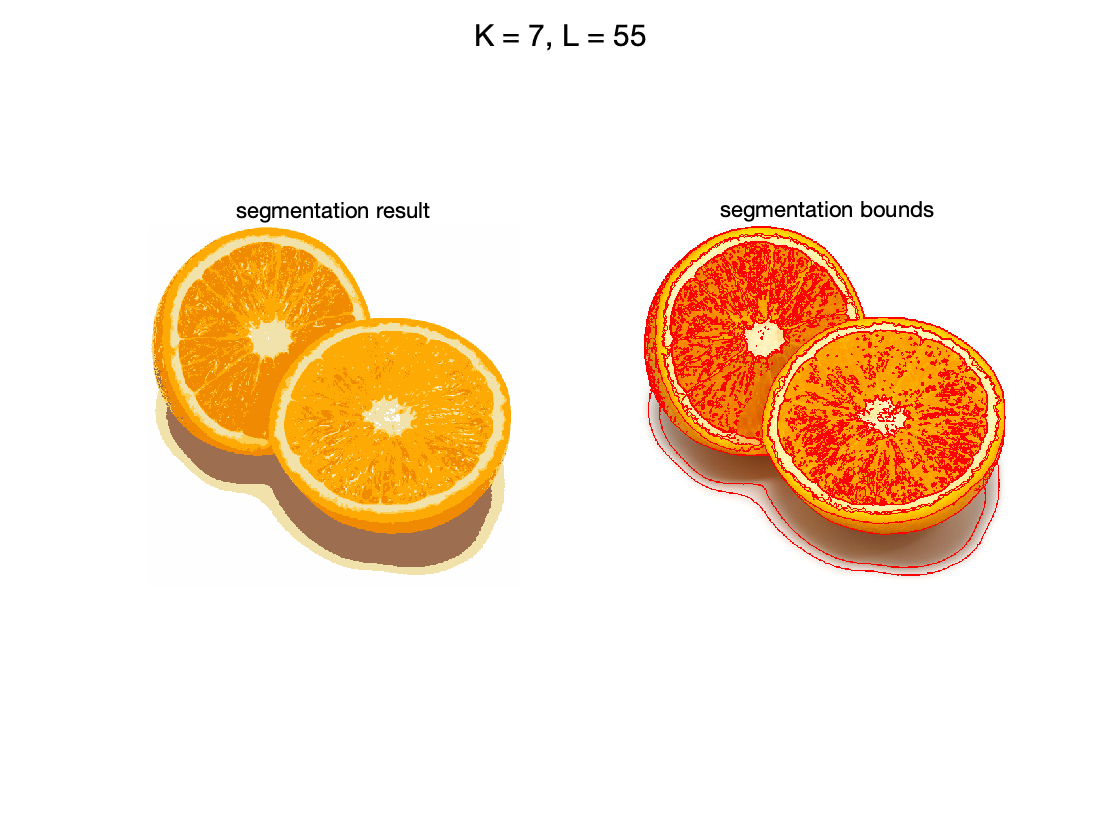

for K = K_list
    [seg, cen, cvgL] = kmeans_segm(image, K, L, 100);
    Inew = mean_segments(image, seg);
    Iover = overlay_bounds(image, seg);
    figure
    subplot(1,2,1)
    imshow(Inew)
    title("segmentation result");
    subplot(1,2,2)
    imshow(Iover)
    title("segmentation bounds");
    sgtitle("K = " + K + ", L = " + cvgL)
end